# Homework 14: 

# Amelia Rotondo, CWID: 887925113

warning off; 

## Section 11.1:

#### Problem 1: 

Equation 11.1.12: $P(t)=\frac{M}{1+e^{-rM(t-t^*)}}$

Logistic Population Growth: $\frac{dP}{dt}=r(M-P)P$

Initial Equation: $t^*=t_0 - (\frac{1}{rM})*ln[\frac{P_0 }{(M-P_0)}]$

Derived Equation: $ln[\frac{P}{(M-P)}]=rMt-rMt^*$

#### Problem 3:

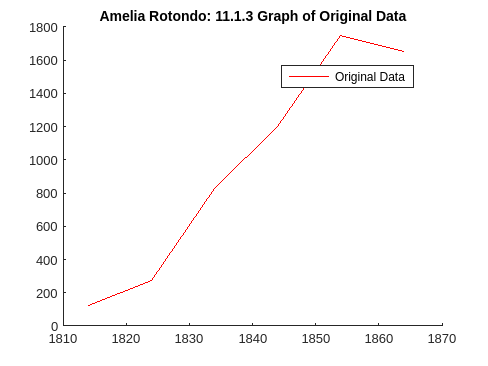

% Initial Data 
t  = 1814:10:1864; 
P  = [125, 275, 830, 1200, 1750, 1650];

% Plot the Data 
figure(1); clf; hold on; 
title('Amelia Rotondo: 11.1.3 Graph of Original Data');
legend('Location', 'best');
plot(t, P, 'r','DisplayName', 'Original Data');

Based on this Plot, I believe that M is about 1600

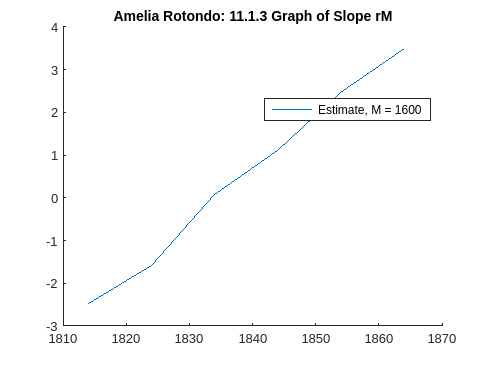

% Add the Estimate of M 
M = 1600; 
P_est = log(P./(M-P));

% Plot the Estimate
figure(2); clf; hold on; 
title('Amelia Rotondo: 11.1.3 Graph of Slope rM');
legend('Location', 'best');
plot(t, P_est, 'DisplayName', 'Estimate, M = 1600');


% Linear Fit 
coeffs = polyfit(t, P_est, 1);
rM_est = coeffs(1); 
t_prime_est = -coeffs(2) / rM_est;
fprintf('rM: %e * %d\nt*: %.9f', (rM_est)/M,M, t_prime_est);

rM: 7.666787e-05 * 1600
t*: 1832.154922500

#### Problem 4: 

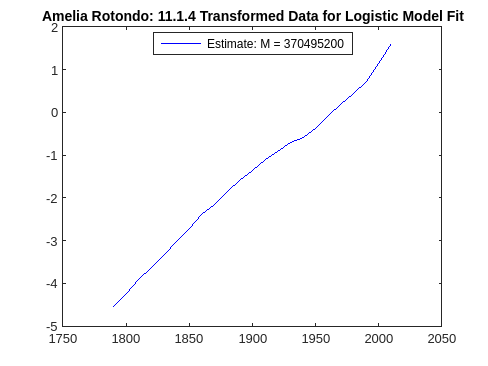

% Original Data
Year = [1790, 1800, 1810, 1820, 1830, 1840, 1850, 1860, 1870, 1880, 1890, 1900, 1910, 1920, 1930, 1940, 1950, 1960, 1970, 1980, 1990, 2000, 2010];
Observed_Population = [3929000, 5308000, 7240000, 9638000, 12866000, 17069000, 23192000, 31443000, 38558000, 50156000, 62948000, 75995000, 91972000, 105711000, 122755000, 131669000, 150697000, 179323000, 203212000, 226505000, 248710000, 281416000, 308746000];
Predicted_Population = [3929000, 5336000, 7227000, 9756000, 13108000, 17505000, 23191000, 30410000, 39370000, 50175000, 62767000, 76867000, 91970000, 107393000, 122396000, 136317000, 148677000, 159230000, 167943000, 174941000, 180440000, 184677000, 187905000];
Percent_Error = [0.0, 0.5, 0.2, 1.2, 1.9, 2.6, 0.0, 3.3, 2.1, 0.0, 0.3, 1.1, 0.0, 1.6, 0.3, 3.5, 1.3, 11.2, 17.4, 22.8, 27.5, 34.4, 39.1];
t = Year; 
P = Observed_Population; 

% Estimate of M
M = max(P)*1.2; 

% Transformation
Transformed_Data = log(P ./ (M - P));

% Linear Fit
coeffs = polyfit(t, Transformed_Data, 1);
rM_est = coeffs(1); 
t_prime_est = -coeffs(2) / rM_est;

% Plotting for visualization (optional)
figure;
plot(t, Transformed_Data, 'b', 'DisplayName', 'Estimate: M = 370495200');
title('Amelia Rotondo: 11.1.4 Transformed Data for Logistic Model Fit');
legend('Location', 'best');

fprintf('rM: %e * %d\nt*: %.9f', (rM_est)/M,M, t_prime_est);

rM: 7.030341e-11 * 370495200
t*: 1957.315640041

## Section 11.2:

#### Problem 3: 

If k = 0.01 $hr^{-1}$ and T = 10 hr, The smallest n such that $R_n > 0.5R$ can be found through the following method: 

% Initial Values
k = 0.01; 
T = 10;   
syms n
Rn = exp(k*T) * (1 - exp(n*k*T)) / (1 - exp(k*T));
R = 1 / (exp(k*T) - 1);

% Find the smallest n such that Rn > 0.5R
n_val = 1; 
while true
    Rn_val = double(subs(Rn, n, n_val)); 
    R_val = double(R);                   
    if Rn_val > 0.5 * R_val
        break
    end
    n_val = n_val + 1;
end

% Display Output
disp(['The smallest n such that Rn > 0.5R is ', num2str(n_val)]);

The smallest n such that Rn > 0.5R is 4


#### Problem 4: 

% Initial values
H = 2;   
L = 0.5; 
k = 0.02; 

% Calculate C0
C0 = (H - L) / (1/k * log(H/L));

% Calculate T
T = 1/k * log(C0/L);

% Display Results
disp(['Initial concentration C0: ', num2str(C0), ' mg/ml']);

Initial concentration C0: 0.02164 mg/ml


disp(['Time interval T between doses: ', num2str(T), ' hours']);

Time interval T between doses: -157.0022 hours


#### Problem 5:


$$L = C_0e^{-kt}\\
t = -\frac{1}{k}ln(\frac{L}{C_0})$$


% Initial values
k = 0.2;    
C0 = 0.1;   
L = 0.03;   

% Calculate time t when concentration falls to L
t = -1/k * log(L/C0);

% Display Result
disp(['The drug will remain effective for approximately ', num2str(t), ' hours.']);

The drug will remain effective for approximately 6.0199 hours.


## Section 11.4:

#### Problem 1a:

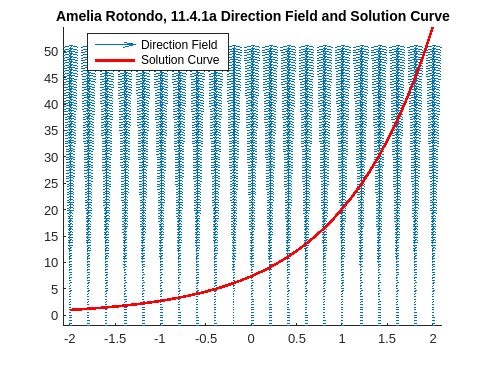

% Initial Values
[x, y] = meshgrid(-2:0.2:2, -2:0.5:50);
dy = y;
dx = ones(size(dy));

% Solving the ODE
odefun = @(x, y) y;
y0 = 1;
[xsol, ysol] = ode45(odefun, [-2, 2], y0);

% Plotting Results
figure(1); clf; hold on; axis tight;
quiver(x, y, dx, dy, 'AutoScaleFactor', 2, 'DisplayName', 'Direction Field');
plot(xsol, ysol, 'r', 'LineWidth', 2, 'DisplayName', 'Solution Curve');
hold off;
title('Amelia Rotondo, 11.4.1a Direction Field and Solution Curve');
legend('Location', 'best');

#### Problem 1d:

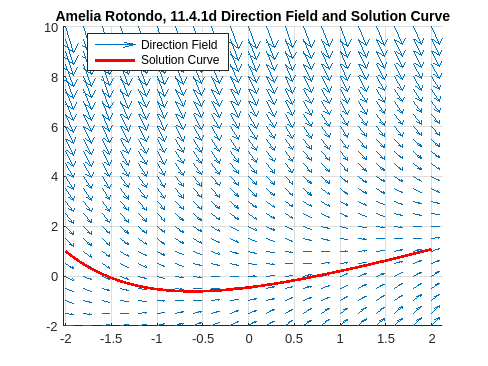

% Initial Values
[x, y] = meshgrid(-2:0.2:2, -2:0.5:10);
dy = x-y;
dx = ones(size(dy));

% Solving the ODE
odefun = @(x, y) x-y;
y0 = 1;
[xsol, ysol] = ode45(odefun, [-2, 2], y0);

% Plotting Results
figure(1); clf; hold on; axis tight;
quiver(x, y, dx, dy, 'AutoScaleFactor', 2, 'DisplayName', 'Direction Field');
plot(xsol, ysol, 'r', 'LineWidth', 2, 'DisplayName', 'Solution Curve');
hold off;
title('Amelia Rotondo, 11.4.1d Direction Field and Solution Curve');
legend('Location', 'best');
grid on;

#### Problem 2: 

#### Problem 5: 

#### Problem 6: 

#### Problem 8: